%Solucion de el taller
clear
clear all 
clc
s=tf('s');
%C=(0.8131*s)+0.9064/(s+1.107)

C =
 
  0.8131 s^2 + 0.9001 s + 0.9064
  ------------------------------
            s + 1.107
 
Continuous-time transfer function.



Gs=(s+4)/((s+2)*(s-1)) %Ejercicio 1 EP<10% Mp=10% ts=4.5s

Gs =
 
     s + 4
  -----------
  s^2 + s - 2
 
Continuous-time transfer function.



Tk=feedback(Gs,1);
Tki=Tk/s % eliminamos %error de posicion

Tki =
 
        s + 4
  -----------------
  s^3 + 2 s^2 + 2 s
 
Continuous-time transfer function.



Tk0=feedback(Tki,1) %Retroalimentamos

Tk0 =
 
          s + 4
  ---------------------
  s^3 + 2 s^2 + 3 s + 4
 
Continuous-time transfer function.



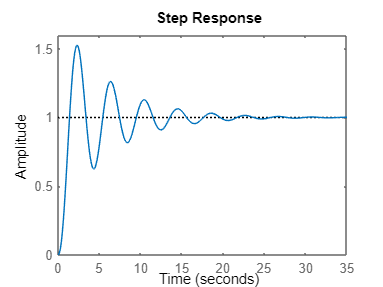

stepplot(Tk0) %visualizamos la grafica

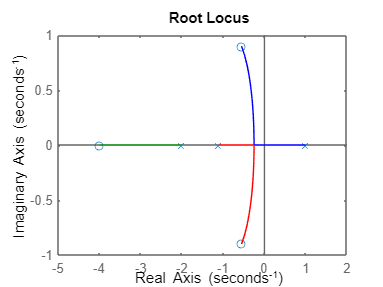

aplicamos %K proporcional
GsC=C*Gs;
rlocus(GsC)

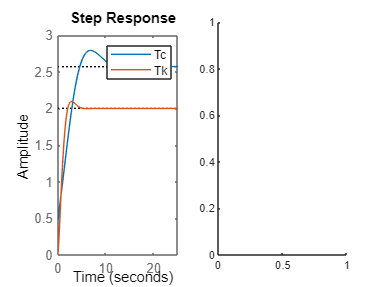

Error using DynamicSystem/step (line 95)
Cannot simulate the time response of improper (non-causal) models.

Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
Su=feedback(C,Gs); %señal de control
subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend